# Stream - groundwater Interaction calculation

In the following section we compare the stream - groundwater interaction terms (SW-GW) calculated using the IWFM approach and the SAFE method. 

For the calculations we use the data from the last time step.

At the current version the computations are meaningful only for the nodes that the river is connected with the groundwater.

## Common Parameters

The length $L$ of the river segments of the nodes are equal to  $L=156\ldotp 25\;m$ except the first and last segment of the river which is half.

L = [156.25/2; 156.25*ones(15,1) ;156.25/2];

The hydraulic conductivity of stream bed material $K_s$ is uniform and equal to

Ks = 2;

The depth is set to

D = 1;

The area of influence$A$ in this example where all the element are orthogonal quadrilateral can simply be calculated as

A = L*156.25;

The ground surface elevation $\textrm{GSE}$, the thickness $W_{\mathrm{aq}}$ of the aquifer and the elevation of the stream bottom $h_b$ for each node are user defined parameters:

GSE = linspace(106, 101,17)';
W_lay = GSE - 50;
hb = linspace(97, 91,17)';

The horizontal and vertical hydraulic conductivity $K_h$ and $K_v$ are 

Kh = 10;
Kv = 10;

Parameters of clogging layer if exists

e_cl = 1; % Thickness
K_cl = 2; % Conductivity Isn't this the same as Ks above?

The wetted perimeter is expressed as $W=f\left(\max \left(h,h_s \right)\right)$,  where $f$is a user defined function as rating table. A plot of the function is shown next

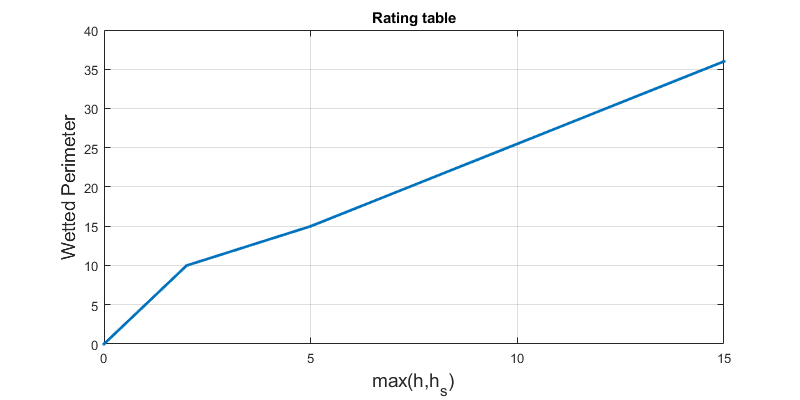

ratingTable = [0 0 0;...
    2 734.94 10;...
    5 3299.29 15;...
    15 19033.6 36;...
    25 41568.45 2000];
clf
set(gcf,'position',[0,0,800,400]);
plot(ratingTable(1:4,1), ratingTable(1:4,3),'.-', "LineWidth",2)
hold on
xlabel('max(h,h_s)',"FontSize",14)
ylabel('Wetted Perimeter',"FontSize",14)
title('Rating table')
grid on
hold off

## IWFM

In IWFM the unit conductance $K_u$ is calculated beforehand. In this example the unit conductance is uniform for all nodes except the nodes that touch the boundary.

Kunit = 30.*Ks.*L.*D; % This seems to be divided by Bed Thickness in code which is 1

#### Simulated data from IWFM output

The hydraulic head $h$ for all river nodes at the last time step is

h = readStreamHead();

The stream surface $h_s$ elevation is obtained by reading the stream hydrograph output file after setting the output type IHSQR = 1

hs = readFinalStreamStage();

Plot

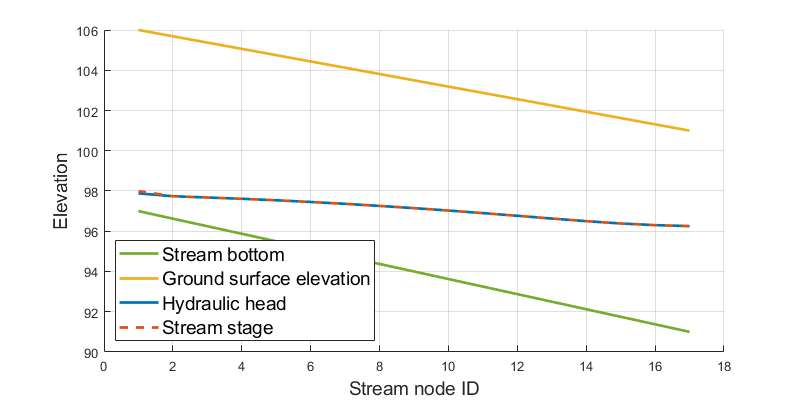

clf 
set(gcf,'position',[0,0,800,400]);
hold on
plot(hb, 'color', '#77AC30','DisplayName','Stream bottom','LineWidth',2)
plot(GSE, 'color', '#EDB120', 'DisplayName','Ground surface elevation','LineWidth',2)
plot(h, 'color', '#0072BD','DisplayName', 'Hydraulic head','LineWidth',2)
plot(hs, '--','color', '#D95319', 'DisplayName','Stream stage','LineWidth',2)
legend("Location","southwest", 'FontSize',14)
xlabel('Stream node ID',"FontSize",14)
ylabel('Elevation',"FontSize",14)
hold off
grid on

We can see that there is a part of the stream (nodes 1-5) that is disconnected from the groundwater.

In the following we will focus on the connected part of the stream.

#### Calculate SW - GW interaction (IWFM)

The wetted perimeter $W_{\textrm{per}}$ is obtain by interpolating the rating table

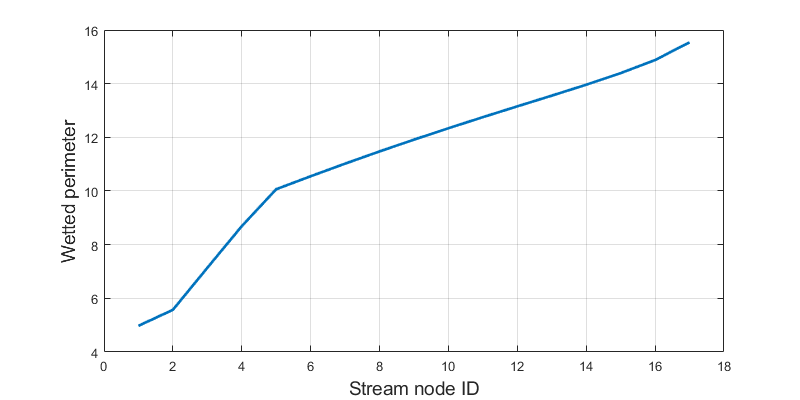

Wper = interp1(ratingTable(:,1), ratingTable(:,3), max(h, hs) - hb);
clf
set(gcf,'position',[0,0,800,400]);
plot(Wper, 'LineWidth',2)
xlabel('Stream node ID',"FontSize",14)
ylabel('Wetted perimeter',"FontSize",14)
grid on

Next the conductance $C_s =K_{u\;} W_{\textrm{per}}$ is 

Cs = Kunit .*  Wper;

The head difference $H_{\textrm{diff}}$ is calculated

Hdiff = max(hs, hb) - max(h, hb);

And finally the stream-groundwater interaction $Q_{\textrm{sint}}$ is

Qsint = Cs .* Hdiff;

Plot the interaction terms

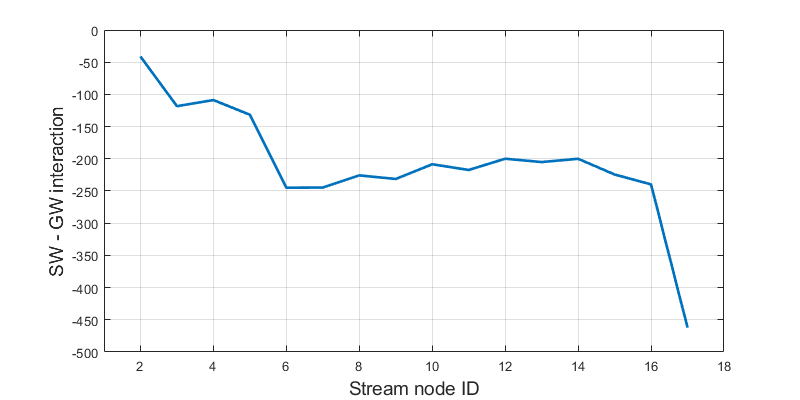

clf
set(gcf,'position',[0,0,800,400]);
plot(2:17, Qsint(2:end), 'LineWidth',2)
xlabel('Stream node ID',"FontSize",14)
ylabel('SW - GW interaction',"FontSize",14)
grid on
xlim([1 18])

## SAFE

### Pre - processing

The following parameters of the SAFE method do not change during the simulation and can be calculated prior to the simulation

SAFE width 


$$W^{\textrm{safe}} =\frac{A}{2L}$$


Wsafe = A ./ (2 .* L) ;

 The SAFE grid size $G^{\textrm{safe}} =2W^{\textrm{safe}}$ which has nothing to do with any mesh element is computed as

Gsafe = 2 .* Wsafe;

### Simulation step

#### Flat conductance

Calculate the river stage $h_{\textrm{stage}}$

h_stage = hs - hb;

Calculate the saturated thickness $D_{\textrm{aq}}$ of the first layer

Daq = h - (GSE - W_lay);

Next, the degree of penetration is computed as

 
$$d_p^N =\;\;\frac{h_{\textrm{stage}} }{D_{\textrm{aq}} }$$
 

d_Np = h_stage ./ Daq;

The average saturated thickness $D_{\textrm{aq}}$ is also used to calculate the normalized wetted perimeter 


$$W_p^N =\frac{W}{D_{\mathrm{aq}} }$$


W_Np = Wper ./ Daq;

next we compute the $\kappa$ value


$$\kappa =e^{-\pi W_p^N }$$


kappa = exp(-pi.*W_Np);

The conductance for a flat recharge area is calculated as


$$\Gamma_{\textrm{flat}} =\frac{1}{2\left\lbrace 1+\frac{1}{\pi }\ln \left(\frac{2}{1-\sqrt{\kappa }}\right)\right\rbrace }$$


G_flat = 1 ./ (2 .* (1 + (1/pi) .* log(2./(1-sqrt(kappa)))));

Plot the above computed values 

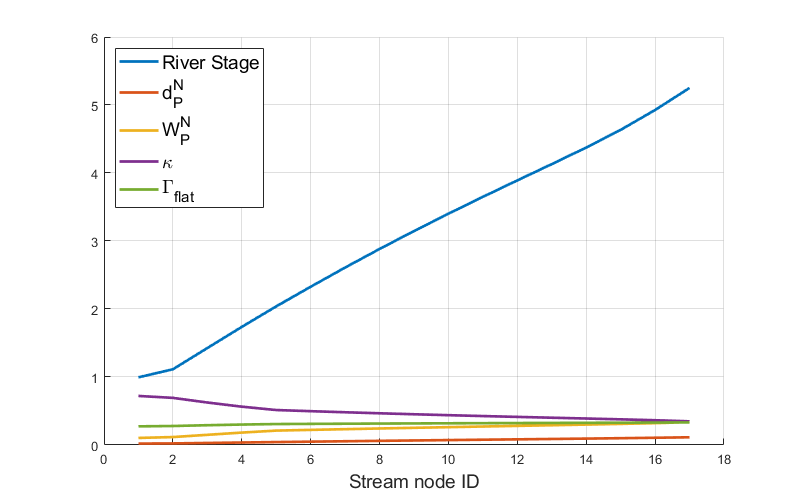

clf
set(gcf,'position',[0,0,800,500]);
hold on
plot(h_stage,'DisplayName','River Stage', 'LineWidth',2)
plot(d_Np,'DisplayName','d_P^N', 'LineWidth',2)
plot(W_Np,'DisplayName','W_P^N', 'LineWidth',2)
plot(kappa,'DisplayName','\kappa', 'LineWidth',2)
plot(G_flat,'DisplayName','\Gamma_{flat}', 'LineWidth',2)
xlabel('Stream node ID',"FontSize",14)
legend('Location',"northwest","FontSize",14)
%patch([1 5 5 1],[0 0 6 6],'blue','FaceAlpha',0.3, 'EdgeColor','none', 'DisplayName', 'Disconnected River')
grid on
hold off

#### Isotropic case

If the aquifer is isotropic the conductance is calculated as


$$\Gamma_{\textrm{iso}} =\Gamma_{\textrm{flat}} \left\lbrack 1+\alpha_1 {\;d}_p^N +\alpha_2 \;{\left(d_p^N \right)}^2 \right\rbrack$$


where the coefficients $a_1 ,a_2$ are estimated as a function of the normalized degree of penetration $d_p^N$ and normalized wetter perimeter $W_p^N$

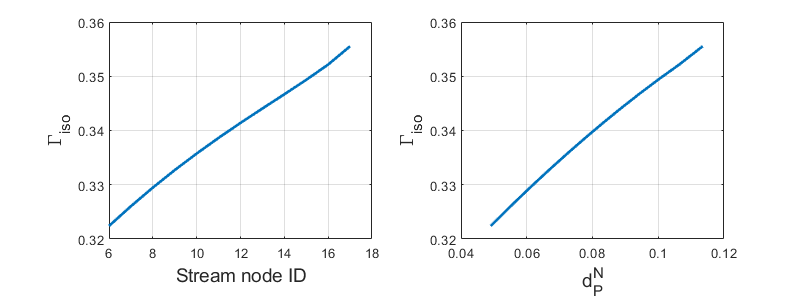

[a1, a2] = safeCoef(d_Np,W_Np);
G_iso = G_flat .* (1 + a1 .* d_Np + a2 .* (d_Np.^2));
clf
set(gcf,'position',[0,0,800,300]);
subplot(1,2,1);
plot(6:17,G_iso(6:end), 'LineWidth',2)
xlabel('Stream node ID',"FontSize",14); 
ylabel('\Gamma_{iso}',"FontSize",14)
grid on;
subplot(1,2,2);
plot(d_Np(6:end), G_iso(6:end), 'LineWidth',2)
xlabel('d_P^N',"FontSize",14); 
ylabel('\Gamma_{iso}',"FontSize",14)
grid on

To estimate the excess far distance $\Delta_{\textrm{iso}}^{\textrm{safe}}$ we have to calculate the half river width $B^{\textrm{safe}} =0\ldotp 5\;W_r$ where $W_r$ is the river width.

The river width is not known but it can be estimated from the equivalent rectangle for the IWFM cross-section. If we preserve the river stage $H^{\textrm{rect}} =h_s$ and the wetted perimeter then $W^{\textrm{rect}} =W_{\textrm{per}}$ then the wetted perimeter can be expressed as $W_{\textrm{per}} =2h_s +W_r$. The wetted perimeter is interpolated from user defined rating tables (see the IWFM calculation).

Wr = Wper - 2.*(hs-hb);
Bsafe = 0.5.*Wr;

 Then the far distance is calculated as


$$\Delta_{\textrm{iso}}^{\textrm{safe}} =\frac{G^{\textrm{safe}} }{4}-B^{\textrm{safe}} -2D_{\textrm{aq}}$$


Delta_iso = Gsafe - Bsafe - 2.*Daq;

Finally the extended value of the dimensionless conductance is calculated as: 


$$\Gamma_{\textrm{iso}-\Delta } =\frac{\Gamma_{\textrm{iso}} }{1+\Gamma_{\textrm{iso}} \frac{\Delta_{\textrm{iso}}^{\textrm{safe}} }{D_{\textrm{aq}} }}$$


G_iso_D = G_iso ./ (1 + G_iso .* (Delta_iso./Daq));

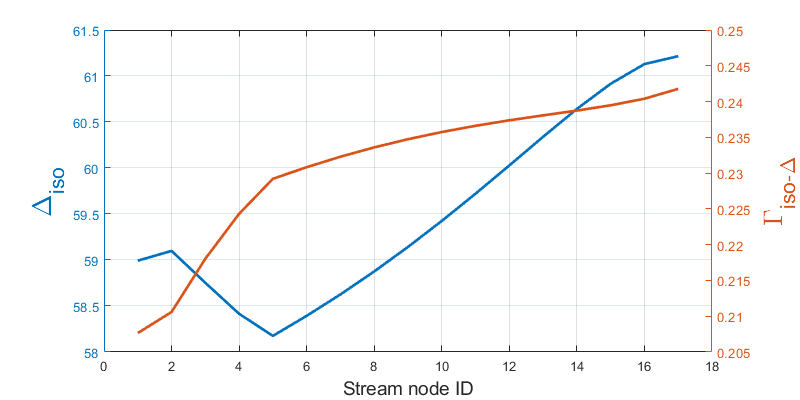

clf
set(gcf,'position',[0,0,800,400]);
yyaxis left
ax = plot(Delta_iso, "LineWidth",2);
ylabel('\Delta_{iso}', "FontSize",20)
lim = axis;
%hold on
%plot([5 5], lim(3:4),'--r')
%text(2,mean(lim(3:4)), {'Disconnected','river'},'HorizontalAlignment',"center", "FontSize",14, "Rotation",45)
%hold off
yyaxis right
plot(G_iso_D, "LineWidth",2)
ylabel('\Gamma_{iso-\Delta}',"FontSize",20)
xlabel('Stream node ID',"FontSize",14)
grid on

For simplicity we set $\Gamma_Q =\Gamma_{\textrm{iso}-\Delta } \;$

G_Q  = G_iso_D;

#### Incipient desaturation

The incipient desaturation is expressed as


$$h_{\mathrm{incip}} =h^o -\frac{B+h_s^o }{K_h \Gamma_Q }\;\frac{h_s^o +h_{\mathrm{ce}} +e_{\mathrm{cl}} }{e_{\mathrm{cl}} }$$


The terms with superscript $o$ are supposed to be the values at the previous step. However in IWFM each time step is solved iteratively until there is a converge. Therefore we can use as old values the ones from the previous converge iteration. For the first iteration we will use the values from the previous step as a starting point.

In the following final head $h$ and river stage $h_s$ are used in place of $h^o$ and $h_s^o$. (I also assume that $B$ is identical to $B^{\textrm{safe}}$)

For the above formula we need the entry pressure term $h_{\textrm{ce}}$ 

h_ce = -0.5;

h_incip = h - ((Bsafe + h_stage)./(Kh.*G_Q)) .* ((h_stage + h_ce + e_cl)./(e_cl));

Test entry pressure values:

The following plots the term$\;\frac{B+h_s^o }{K_h \Gamma_Q }\;\frac{h_s^o +h_{\textrm{ce}} +e_{\textrm{cl}} }{e_{\textrm{cl}} }$ for a number of entry pressure values.

When the term is positive then $h>h_{\textrm{incip}}$ therefore the connection remains saturated.

If the term is negative then the $h_{\textrm{incip}} >h$ and the connection is unsaturated

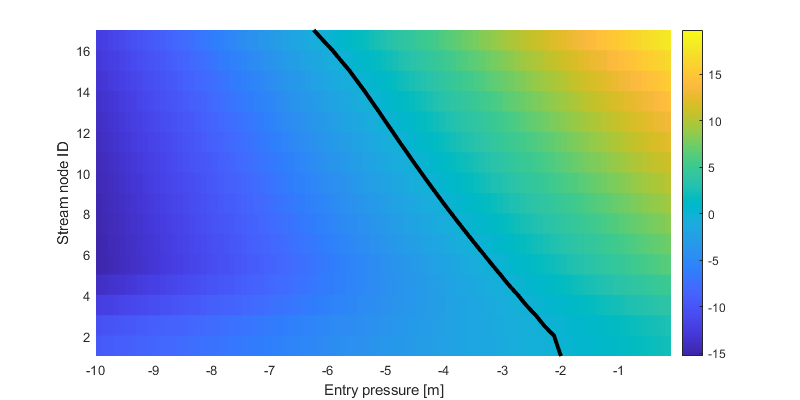

h_ce = -0.1:-0.1:-10;
cc = zeros(length(h), length(h_ce));
h_incip_test = zeros(length(h), length(h_ce));
for ii = 1:length(h_ce)
    cc(:,ii) = ((Bsafe + h_stage)./(Kh.*G_Q)) .* ((h_stage + h_ce(ii) + e_cl)./(e_cl));
    h_incip_test(:,ii) = h - cc(:,ii);
end
[xx, yy] = meshgrid(h_ce,1:17);
clf
surf(xx, yy, cc, "EdgeColor","none")
hold on
M = contour(xx, yy, cc, [0 0]);
plot3(M(1,2:end), M(2,2:end),30*ones(size(M,2)-1,1),'k','LineWidth',3)
xlabel('Entry pressure [m]')
ylabel('Stream node ID')
view(0,90);
colorbar
hold off

Plot the comparison between incipient desaturation and the groundwater head

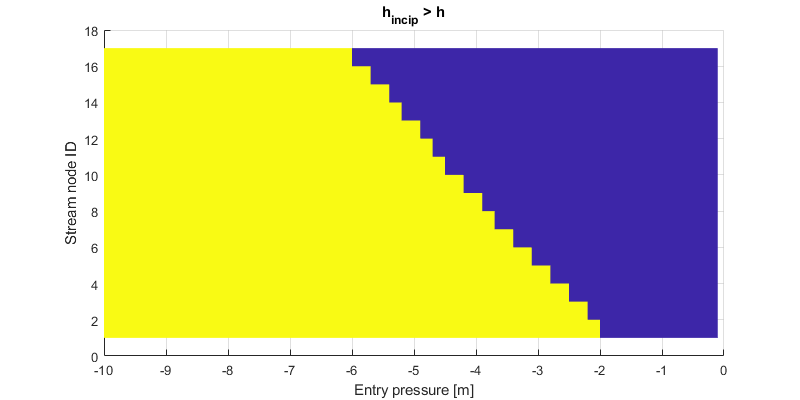

clf
surf(xx,yy,1*(h_incip_test > repmat(h,1,length(h_ce))), 'EdgeColor',"none")
view(0,90)
title('h_{incip} > h')
xlabel('Entry pressure [m]')
ylabel('Stream node ID')

#### Calculation of stream - groundwater interaction

The sw-gw interaction finally can be calculated as


$$Q_{\textrm{sint}}^{\textrm{safe}} =2\;{\textrm{LK}}_h \Gamma_Q \left({\;h}_s -h\right)$$


where $h$ is the groundwater head and $h_s$ is the river head and $K_h$ is the horizontal hydraulic conductivity. These are estimated from the previous step.

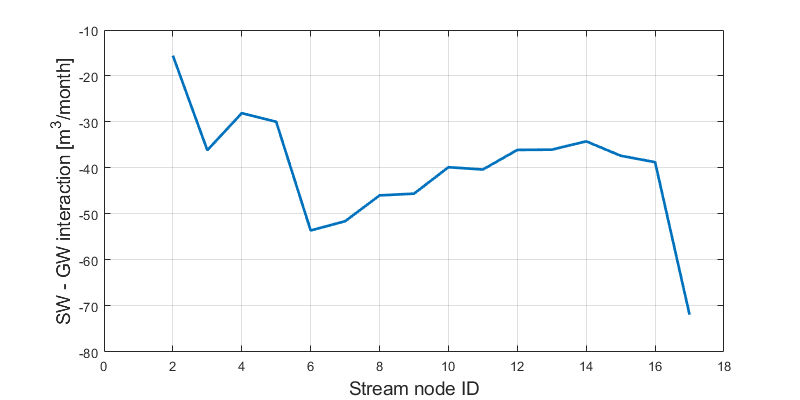

Q_sint_safe = 2.*L.*Kh.*G_Q.*(hs - h);
clf
set(gcf,'position',[0,0,800,400]);
plot(2:17,Q_sint_safe(2:end)*30,'LineWidth',2)
xlabel('Stream node ID',"FontSize",14)
ylabel('SW - GW interaction [m^3/month]',"FontSize",14)
xlim([0 18])
grid on

The above figure plots only the nodes 6-17 where the river is connected to the water table. 

## Functions

function [a1, a2] = safeCoef(d_Np, W_Np)
    a1 = nan(length(d_Np),1);
    a2 = nan(length(d_Np),1);
    for ii = 1:length(d_Np)
        if W_Np(ii) <= 1 
            if d_Np(ii) <= 0.2
                a1(ii) = 0.89;
                a2(ii) = -2.43;
            elseif d_Np(ii) > 0.2 && d_Np(ii) <= 0.5
                a1(ii) = 0.538;
                a2(ii) = -0.387;
            end
        elseif W_Np(ii) > 1 && W_Np(ii) <= 3
            if d_Np(ii) <= 0.2
                a1(ii) = 0.819;
                a2(ii) = -1.34;
            elseif d_Np(ii) > 0.2 && d_Np(ii) <= 0.5
                a1(ii) = 0.672;
                a2(ii) = -0.542;
            elseif d_Np(ii) > 0.5 && d_Np(ii) <= 0.9
                a1(ii) = 0.567;
                a2(ii) = -0.33;
            end
        end
    end
end

function h = readStreamHead()
    XY = readIWFM_Nodes(fullfile('Preprocessor','Ex1_Nodes.dat'));
    H = readIWFM_headalloutput(fullfile('Results','Ex1_GW_HeadAll.out'), false);
    id_stream = find(XY(:,2) == 625);
    [~, ind_sort] = sort(XY(id_stream,1),'descend');
    h = H{end,2}(id_stream(ind_sort),1);
end

function hs = readFinalStreamStage()
    % There is a weird discrepency between the printed values and the ones used
    % in the simulation. therefore I'm pasting here directly the values
    % copied from the simulation.
    % h = readStreamStage(fullfile('Results','Ex1_Stream_hyd.dat'),12);
    % hs = h.Hs(:,end)/1000;
    hs = [97.9951867561372
        97.7385114880494
        97.6757322954899
        97.6117648925185
        97.5386058367031
        97.4522238991826
        97.3594320451257
        97.2578014924688
        97.1464289675067
        97.0268978473296
        96.8992819355494
        96.7663793294663
        96.6305863420342
        96.4996719113822
        96.3843371384805
        96.3016814659060
        96.2512570250855];
end